# 11주차_피드백 성능 #1

## `Cruise Control`

## 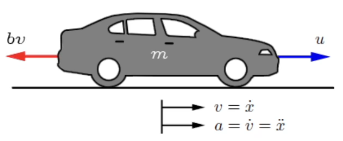

### `Systme equations`

    
$$\begin{array}{l}
m\;\dot{\;v} +\mathrm{bv}=u\\
y=v
\end{array}$$


### `system parameters`

`    (m) vehicle mass            1000 kg`

`    (b) damping coefficient     50 N.s/m`

`    (u) nominal control force   500 N`

### `State-space model`

    
$$\begin{array}{l}
\dot{\;\mathit{\mathbf{x}}} \;=\;\dot{\;v} \;=\;\left\lbrack \begin{array}{c}
-\frac{b}{m}
\end{array}\right\rbrack v\;+\left\lbrack \begin{array}{c}
\frac{1}{m}
\end{array}\right\rbrack u\\
y=\left\lbrack \begin{array}{c}
1
\end{array}\right\rbrack v
\end{array}$$


m = 1000;
b = 50;

A = -b/m;
B = 1/m;
C = 1;
D = 0;

cruise_ss = ss(A,B,C,D);

### `Transfer function model`

    
$$P\left(s\right)=\frac{V\left(s\right)}{U\left(s\right)}=\frac{1}{\mathrm{ms}+b}$$


s = tf('s');
P_cruise = 1/(m*s+b);

## Open-loop step response

m = 1000;
b = 50;
u = 500;

s = tf('s');
P_cruise = 1/(m*s+b);

step(u*P_cruise);
title('Open-loop Step Response');
ylabel('Velocity (m/s)');

## `Mass`

m =1000;
b = 50;
u = 500;

s = tf('s');
P_cruise = 1/(m*s+b);

step(u*P_cruise);
axis([0 100 0 20]);
title('Effect of Vehicle Mass on Open-loop Step Response');
ylabel('Velocity (m/s)');

## `Damping Coefficient`

m = 1000;
b = 50;
u = 500;

s = tf('s');
P_cruise = 1/(m*s+b);

step(u*P_cruise);
axis([0 100 0 20]);
title('Effect of Vehicle Drag on Open-loop Step Response');
ylabel('Velocity (m/s)');

## `Step Input`

m = 1000;
b = 50;
u = 500;

s = tf('s');
P_cruise = 1/(m*s+b);

step(u*P_cruise);
axis([0 100 0 20]);
title('Effect of Vehicle Drivetrain on Open-loop Step Response');
ylabel('Velocity (m/s)');

## `DC Motor`

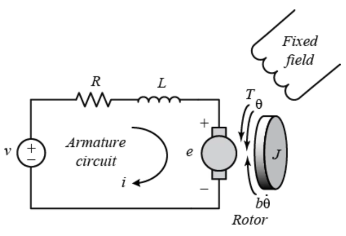

### `system parameters`

`    (J)    moment of inertia of the rotor    0.01 kg.m^s`

`    (b)    motor viscous friction constant   0.1 N.m.s`

`    (Ke)   electromotive force constant      0.01 V/rad/sec`

`    (Kt)   motor torque constant             0.01 N.m/Amp`

`    (R)    electric resistance               1 Ohm`

`    (L)    electric inductance               0.5 H`

### `Systme equations`

    
$$\begin{array}{l}
T=K_t \cdot \;i\\
e=K_e \cdot \dot{\;\theta } 
\end{array}$$
            

    
$$K_t =K_e =K$$


    
$$\begin{array}{l}
J\ddot{\;\theta } +b\dot{\;\theta } =K\cdot i\\
L\frac{\;di}{dt}+R\cdot i=V-K\cdot \dot{\;\theta \;} 
\end{array}$$


### `Transfer function model`

    
$$\begin{array}{l}
\left(Js^2 +bs\right)\cdot \Theta \left(s\right)=K\cdot I\left(s\right)\\
\left(Ls+R\right)\cdot I\left(s\right)=V\left(s\right)-K\cdot \;s\Theta \;\left(s\right)
\end{array}$$


        
$$\left(Js^2 +b\;s\right)\cdot \Theta \left(s\right)=K\cdot \frac{V\left(s\right)-K\cdot \;s\Theta \;\left(s\right)\;}{L\;s+R}$$


        
$$P\left(s\right)=\frac{s\;\Theta \left(s\right)\;}{V\left(s\right)}=\frac{K}{\left(J\;s+b\right)\cdot \left(L\;s+R\right)+K^{2\;} }$$


J = 0.01;
b = 0.1;
K = 0.01;
R = 1;
L = 0.5;

s = tf('s');
P_motor = K/((J*s + b)*(L*s+R) + K^2);

### `State-space model`

motor_ss = ss(P_motor);